# Linear regression, GLMs and model comparison

## 2.1. Mapping place fields with Generalized Linear Models (GLM)

The Generalized Linear Model (GLM) is a powerful analytical tool widely used to explore and quantify the relationship between neural activity and external stimuli or behavioral variables. GLMs extend the classical linear regression framework by accommodating a variety of response distributions, making them suitable for modeling neural spike data that often exhibit non-Gaussian properties. It also enable us to incorporate multiple predictors, making it possible to disentangle how different variables, which may be correlated in the input, influence neural responses. In this tutorial, we will fit GLMs to our particular dataset, assuming a Poisson distribution of spikes, to uncover how firing rates are modulated by spatial positions and speed. By estimating and comparing different GLM models with respect to their prediction accuracy, we will determine the most parsimonious model that accurately explains the observed neural responses and identify which predictors significantly contribute to the neural response of each neurons.

Throughout this tutorial, we will walk through the steps of design matrix creation, GLM estimation, and model comparison. We will assess the tuning curves of individual neurons for both position and speed and compare these results to classical place field analyses. By the end of this tutorial, you will have a comprehensive understanding of how to apply the Poisson GLM to neurophysiological data and gain more insights into the encoding of spatial positions and speed in our dataset. We will also discuss potential limitations and considerations, such as the importance of cross-validation for robust model assessment. 

The analyses described in this tutorial can be run by calling the following set of functions:

%define parameters for GLMs
glmsparams = DefineGLMsParams(Nav,Spk);

%change parameters here if necessary

%GLMs estimation without cross-validation
GLMs = GLMAnalyses(Nav, Spk.spikeTrain, glmsparams);%estimate GLMs

%GLMs estimation with cross-validation
GLMs = GLMAnalysesCV(Nav, Spk.spikeTrain, glmsparams);

#### 2.2.1 Loading and preprocessing the behavioral and spiking data as done in Tutorial1

%Path to the directory where the data are stored
datadirpath = [filesep 'MATLAB Drive' filesep 'School' filesep 'Dataset' filesep 'Session1'];

%Load the default parameters for loading the data
loadparams = DefineLoadParams(datadirpath);

%Load the behavioral data into a matlab structure.
Nav = LoaddataNav(loadparams);

%Load the spiking data into a matlab structure.
Spk = LoaddataSpk(loadparams, Nav.sampleTimes);

#### 2.2.2 Parameters for estimating GLMs

Defining a set of parameters needed to GLMs, such as the bin size used for discretizing the position or speed variables or the experimental conditions over which place fields should be estimated.

%Experimental condition over which GLMs will be estimated
glmsparams.condition = [1 3 5];

%lap type over which GLMs will be estimated
glmsparams.dir = 1;

%lap types over which place fields will be estimated
glmsparams.laptype = [-1 0 1];

%Minimum speed threshold over which GLMs will be computed
glmsparams.spdthreshold = 2.5;

%Subset of cells for which GLMs will be computed
glmsparams.cellidx = true(1, size(Spk.spikeTrain, 2));

%Sampling rate of the data
glmsparams.sampleRate = 1 / nanmean(diff(Nav.sampleTimes));

%Range of spatial positions over which GLMs will be estimated (in cm).
glmsparams.Xrange = [0 100];

%Size of the position bins (in cm).
glmsparams.Xbinsize = 4;

%Size of the gaussian window for smoothing position tuning curves (in cm).
glmsparams.Xsmthbinsize = 2;

%Size of the gaussian window for smoothing position tuning curves 
%(in bins).
glmsparams.XsmthNbins = glmsparams.Xsmthbinsize / glmsparams.Xbinsize;

%Edges of position bins used to discretize positions
glmsparams.Xbinedges = [glmsparams.Xrange(1):glmsparams.Xbinsize:glmsparams.Xrange(2)];

%Range of speeds over which GLMs will be estimated (in cm/s).
glmsparams.Spdrange = [5 55];

%Size of the speed bins (in cm/s).
glmsparams.Spdbinsize = 5;

%Size of the gaussian window for smoothing speed tuning curves (in cm/s).
glmsparams.Spdsmthbinsize = 5;

%Size of the gaussian window for smoothing speed tuning curves (in bins).
glmsparams.SpdsmthNbins = glmsparams.Spdsmthbinsize / glmsparams.Spdbinsize;

%Edges of speed bins used to discretize speed
glmsparams.Spdbinedges = glmsparams.Spdrange(1):glmsparams.Spdbinsize:glmsparams.Spdrange(2);

%Occupancy threshold above which predictors are included in the GLM
%estimate.
glmsparams.occ_th = 0;

%Minimal number of spikes to consider a cell for GLM estimation
glmsparams.nspk_th = 10;

%Number of folds to consider for cross-validation
glmsparams.kfold = 10;

%Whether or not the GLM model should include a constant term
glmsparams.intercept = true;

%Type of regularization in glmnet: 1 for lasso, 0 for ridge, elsticnet for
%everything in between
glmsparams.alpha = 1;

%Maximal number of passes over the data before reaching convergence
glmsparams.maxit = 10^3;

%Convergence threshold for coordinate descent, expressed as a fraction of
%the null deviance.
glmsparams.thresh = 10^-3;

%P-value threshold for considering a predictor as significantly
%contributing to the cell response.
glmsparams.pval_th = 0.05;

This set of parameters can be obtained by calling DefineGLMsParams.m

glmsparams = DefineGLMsParams(Nav,Spk);

#### 2.1.3 Estimate a GLM model including positions and speeds as predictors

In this analysis, we will estimate a Generalized Linear Model (GLM) while assuming a Poisson distribution. The GLM will incorporate spatial positions and running speed as predictors to capture the neural response variability. Specifically, we will focus on the left-to-right directional movement. To initiate the process, we will begin by subsetting the relevant variables: Nav.Xpos, Nav.Spd, and Spk.spikeTrain.

%We want left to right direction (Nav.Xdir = 1) so let's first change this
%parameter in the glmsparams structure.
glmsparams.dir = 1;

%Subset of time indices over which GLMs will be computed
tidx = ismember(Nav.Condition, glmsparams.condition) &...
       ismember(Nav.XDir, glmsparams.dir) &...
       Nav.Spd >= glmsparams.spdthreshold &...
       ~isnan(Nav.Xpos);
          
%Subset of cells for which we'll compute tuning curves
cellidx = find(glmsparams.cellidx & sum(Spk.spikeTrain(tidx,:), 1) > glmsparams.nspk_th);

%Subseting position, speed and spike trains.
spikeTrain = Spk.spikeTrain(tidx,cellidx);
Xpos = Nav.Xpos(tidx);
Spd = Nav.Spd(tidx);

Let's first discretize positions and speeds.

%Discretizing position vector according to glmsparams.Xbinedges
Xpos_discrete = discretize(Xpos, glmsparams.Xbinedges);

%Discretizing speed vector according to glmsparams.Spdbinedges
%Speeds are first clamped within the speed range
Spd(Spd > glmsparams.Spdbinedges(end)) = glmsparams.Spdbinedges(end);
Spd(Spd < glmsparams.Spdbinedges(1)) = glmsparams.Spdbinedges(1);

Spd_discrete = discretize(Spd, glmsparams.Spdbinedges);

With the essential variables in place, the next step involves constructing the design matrix. This matrix will encapsulate the predictors, namely spatial positions and running speed into a 2d array where each columns correspond to different bins of positons and speed and contains ones whenever the animal is in a particular bin.

%Number of position bins
nXbins = numel(glmsparams.Xbinedges) - 1;

%Number of speed bins
nSpdbins = numel(glmsparams.Spdbinedges) - 1;

%Number of data points
ntimepts = size(spikeTrain,1);

%Build the matrix of predictors (design matrix) for positions and for speed
Xmat = full(sparse(1:ntimepts, Xpos_discrete, ones(ntimepts,1), ntimepts, nXbins));
Smat = full(sparse(1:ntimepts, Spd_discrete, ones(ntimepts,1), ntimepts, nSpdbins));

%Removing positions for which occupancy is below the threshold
validXpos = find(sum(Xmat, 1) > glmsparams.occ_th);
Xmat = Xmat(:,validXpos);
validSpd = find(sum(Smat, 1) > glmsparams.occ_th);
Smat = Smat(:,validSpd);

%Number of valid predictors for positions and speed
nvalidXpos = numel(validXpos);
nvalidSpd = numel(validSpd);

%Build the design matrix for the (Position , Speed) model
XSmat = cat(2, Xmat, Smat);

%keep track of the indices of predictors related to position in the full
%design matrix
Xidx = 1:nvalidXpos;

%keep track of the indices of predictors related to speed in the full
%design matrix
Sidx = (nvalidXpos + 1):(nvalidXpos + nvalidSpd);

Proceeding from the design matrix, we can now estimate the GLM model for each individual cell. But before delving into this, we need to establish a set of options for the GLM solver. These options will govern various aspects of the estimation procedure.

%Distribution of the GLM model
family = 'poisson';
%Initializing the options for fitting the GLM with glmnet
options = glmnetSet;
%Number of lambda values used for the regularization path
options.nlambda = 100;
%Whether or not the predictors are randomized. The estimated coefficients
%are always returned on the original scale
options.standardize = true;
%Whether or not to include a constant term in the model (i.e. a0 in the
%equation above)
options.intr = glmsparams.intercept;
%Type of regularization: 1 for lasso, 0 for ridge and elastic net for in
%between
options.alpha = glmsparams.alpha;
%Maximum number of passes over the data for all lambda values
options.maxit = glmsparams.maxit;
%Convergence threshold for the gradient descent (fraction of the null
%deviance)
options.thresh = glmsparams.thresh;

Now we can estimate the GLM model including position and speed as predictors, using the **glmnet** algorithm.

%Number of cells selected for estimating tuning curves
ncells = size(spikeTrain, 2);

%Sampling rate
sampleRate =  1 / nanmean(diff(Nav.sampleTimes));

%Computing position and speed tuning curves with glmnet for the position x
%speed model.
mapXS_X = NaN(ncells, nXbins);
mapXS_S = NaN(ncells, nSpdbins);
LLH_XS = NaN(ncells, 1);
for icell = 1:ncells
    %Estimating the full model with glmnet
    options.lambda = [];
    gfit = glmnet(XSmat, spikeTrain(:,icell), family, options);
    options.lambda = [gfit.lambda ; 0];
    gfit = glmnet(XSmat, spikeTrain(:,icell), family, options);

    %Computing the output of the full model without regularization.
    yfit = exp(gfit.a0(end) + XSmat * gfit.beta(:,end));

    %Alternatively, we could call the glmnetPredict function to get the
    %reconstructed response.
    %yfit = glmnetPredict(gfit, XSmat, 0, 'response');
    
    %Computing the log likelihood of the fitted data under the model
    LLH_XS(icell) = computeLLH_poisson(spikeTrain(:,icell), yfit);
    
    %Getting the position ansd speed tuning curves with no regularization.
    %To get curves equivalent to tuning curves, we marginalize out the
    %effect of other variables by adding their mean to the tuning curve
    %coefficients. Then because it is a Poisson distribution that we're 
    %using we need to invert the log link function (taking the exponential)
    %and we convert it to spike / s by multiplying with the sampling rate.
    mapXS_X(icell,validXpos) = sampleRate * exp(gfit.a0(end) + gfit.beta(Xidx,end) + mean(gfit.beta(Sidx,end)));
    mapXS_S(icell,validSpd) = sampleRate * exp(gfit.a0(end) + gfit.beta(Sidx,end) + mean(gfit.beta(Xidx,end)));
    
    %Smoothing the tuning curves with a Gaussian
    mapXS_X(icell,:) = GaussianSmooth1D(mapXS_X(icell,:), glmsparams.XsmthNbins);
    mapXS_S(icell,:) = GaussianSmooth1D(mapXS_S(icell,:), glmsparams.SpdsmthNbins);
end

But how to know whether the (position,speed) model is the right one for a given neuron?

The suitability of the (position, speed) model for a specific neuron requires model comparison. This means, we need to evaluate various models and select the most parsimonious one that offers significantly improved prediction accuracy compared to simpler alternatives. As a result, it becomes necessary to estimate tuning curves for scenarios in which either position or speed serves as the sole predictor. 

We will begin by considering the position-only model.

%Computing position tuning curves with glmnet for the position-only model.
mapX = NaN(ncells, nXbins);
LLH_X = NaN(ncells, 1);
for icell = 1:ncells
    %First call to get the set of lambda values used for the regularization
    %path
    options.lambda = [];
    gfit = glmnet(Xmat, spikeTrain(:,icell), family, options);
    
    %Calling glmnet again after adding lambda = 0 as an additional
    %regularization value.
    options.lambda = [gfit.lambda ; 0];
    gfit = glmnet(Xmat, spikeTrain(:,icell), family, options);

    %Computing the output of the full model without regularization.
    yfit = exp(gfit.a0(end) + Xmat * gfit.beta(:,end));

    %Computing the log likelihood of the fitted data under the model
    LLH_X(icell) = computeLLH_poisson(spikeTrain(:,icell), yfit);
    
    %Getting the tuning curve estimated for the last lambda value (i.e.
    %lambda = 0)
    mapX(icell,validXpos) = sampleRate * exp(gfit.a0(end) + gfit.beta(:,end));

    %Smoothing the tuning curve with a Gaussian
    mapX(icell,:) = GaussianSmooth1D(mapX(icell,:), glmsparams.XsmthNbins);
end

Then we do the same thing for the Speed-only model

%Computing speed tuning curves with glmnet for the speed-only model. 
mapS = NaN(ncells, nSpdbins);
LLH_S = NaN(ncells, 1);
for icell = 1:ncells
    %Estimating speed tuning curve with glmnet
    options.lambda = [];
    gfit = glmnet(Smat, spikeTrain(:,icell), family, options);
    options.lambda = [gfit.lambda ; 0];
    gfit = glmnet(Smat, spikeTrain(:,icell), family, options);

    %Computing the output of the full model without regularization.
    yfit = exp(gfit.a0(end) + Smat * gfit.beta(:,end));

    %Computing the log likelihood of the fitted data under the model
    LLH_S(icell) = computeLLH_poisson(spikeTrain(:,icell), yfit);
    
    %Getting speed tuning curve with no regularization
    mapS(icell,validSpd) = sampleRate * exp(gfit.a0(end) + gfit.beta(:,end));
    
    %Smoothing the tuning curve with a Gaussian
    mapS(icell,:) = GaussianSmooth1D(mapS(icell,:), glmsparams.SpdsmthNbins);
end

Lastly, our analysis involves comparing the single-variable models to the constant mean model. Therefore, we will compute the log likelihood for this specific model as well.

%Computing the log likelihood of the data under a constant mean model
LLH_cst = NaN(ncells, 1);
for icell = 1:ncells
    yfit = nanmean(spikeTrain(:,icell));
    LLH_cst(icell) = computeLLH_poisson(spikeTrain(:,icell), yfit);
end

In order to gauge the performance of these four distinct models, we will use a forward selection procedure, using the likelihood ratio test for assessing statistical significance. This rigorous comparison will enable us to identify the most parcimonuous model that best explains the neuronal response (based on their log likelihood values).

%Model selection: which of he tree models estimated above is best for each
%cell

%First identifying which single-variable model is best for each cell
[~, bestsinglemodel] = max([LLH_X LLH_S], [], 2);


bestmodel = zeros(ncells, 1);
pval_X = NaN(ncells, 1);
pval_S = NaN(ncells, 1);

%First considering cells for which position alone is better than speed
%alone to explain the response.
bestXcellidx = bestsinglemodel == 1;

%Comparing position-only model to the constant mean model and to the
%full model to test the significance of adding each variable to the model
if sum(bestXcellidx) > 0
    %Comparing position-only model to the constant mean model to get the
    %significance of adding position to fit the cell response.
    dof = nvalidXpos;
    [~, pval_X(bestXcellidx)] = lratiotest(LLH_X(bestXcellidx), LLH_cst(bestXcellidx), dof);
    
    %Comparing position-only model to the full model to get the
    %significance of adding speed to the position-only model.
    dof = (1 + nvalidXpos + nvalidSpd) - (1 + nvalidXpos);
    [~, pval_S(bestXcellidx)] = lratiotest(LLH_XS(bestXcellidx), LLH_X(bestXcellidx), dof);
    
    %If adding speed leads to a significant improvement of the model, we
    %consider the full model as the best model.
    bestmodel(bestXcellidx & pval_S <= glmsparams.pval_th) = 3;
    %Otherwise, we consider the position-only model as the best one.
    bestmodel(bestXcellidx & pval_S > glmsparams.pval_th) = 1;
    %All of that provided that the position-only model is significantly
    %better than the constant mean model in the first place.
    bestmodel(bestXcellidx & pval_X > glmsparams.pval_th) = 0;
end

%Now doing the same thing for cells for which speed alone is better than
%positin alone to explain the response.
bestScellidx = bestsinglemodel == 2;

%Comparing speed-only model to the constant mean model and to the
%full model to test the significance of adding each variable to the model
if sum(bestScellidx) > 0
    %Comparing speed-only model to the constant mean model to get the
    %significance of adding speed to fit the cell response.
    dof = nvalidSpd;
    [~, pval_S(bestScellidx)] = lratiotest(LLH_S(bestScellidx), LLH_cst(bestScellidx), dof);
    
    %Comparing speed-only model to the full model to get the
    %significance of adding position to the speed-only model.
    dof = (1 + nvalidXpos + nvalidSpd) - (1 + nvalidSpd);
    [~, pval_X(bestScellidx)] = lratiotest(LLH_XS(bestScellidx), LLH_S(bestScellidx), dof);
    
    %If adding position leads to a significant improvement of the model, we
    %consider the full model as the best model.
    bestmodel(bestScellidx & pval_X <= glmsparams.pval_th) = 3;
    %Otherwise, we consider the speed-only model as the best one.
    bestmodel(bestScellidx & pval_X > glmsparams.pval_th) = 2;
    %All of that provided that the speed-only model is significantly
    %better than the constant mean model in the first place.
    bestmodel(bestScellidx & pval_S <= glmsparams.pval_th) = 0;
end

This entire analysis can be run by calling **GLMAnalyses.m**

GLMs = GLMAnalyses(Nav, Spk.spikeTrain, glmsparams);

Visualize the tuning curves for position and speed for all neurons.

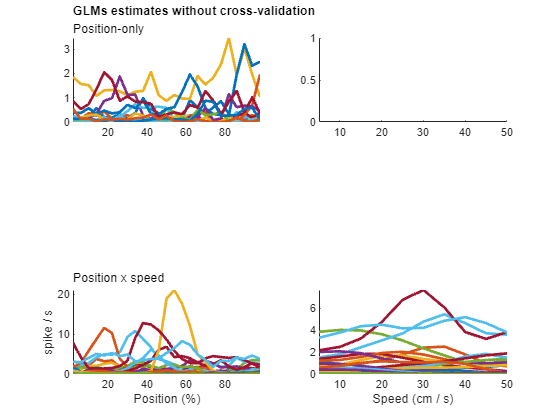

%Plotting position and speed tuning curves side by side
figure;

modelList = [1 2 3];
modelNames = {'Position-only', 'Speed-only', 'Position x speed'};
nmodels = numel(modelList);

for imodel = 1:nmodels
    if sum(GLMs.bestmodel == modelList(imodel)) > 0
        subplot(nmodels,2,(imodel-1)*2 + 1);
        plot(GLMs.Xbincenters, GLMs.mapX(GLMs.bestmodel == modelList(imodel),:)','linewidth', 2);
        subtitle(modelNames{imodel});
        mX = max(GLMs.mapX(GLMs.bestmodel == modelList(imodel),:), [], 'all');
        if ~isnan(mX)
            set(gca,'Ylim', [0 mX]);
        end
        set(gca,'Xlim', [GLMs.Xbincenters(1) GLMs.Xbincenters(end)],'Box', 'off','TitleHorizontalAlignment','left');
        
        subplot(nmodels,2,(imodel-1)*2 + 2);
        plot(GLMs.Spdbincenters, GLMs.mapS(GLMs.bestmodel == modelList(imodel),:)','linewidth', 2);
        mS = max(GLMs.mapS(GLMs.bestmodel == modelList(imodel),:), [], 'all');
        if ~isnan(mS)
            set(gca,'Ylim', [0 mS]);
        end
        set(gca,'Xlim', [GLMs.Spdbincenters(1) GLMs.Spdbincenters(end)],'Box', 'off','TitleHorizontalAlignment','left');
    end
end
%labels title etc
subplot(nmodels,2, 2*nmodels - 1);
xlabel('Position (%)');
ylabel('spike / s');

subplot(nmodels,2, 2*nmodels);
xlabel('Speed (cm / s)');

subplot(nmodels,2, 1);
title('GLMs estimates without cross-validation')

If you're familiar with placec ells data, you'll notice that somehting is off: the fraction of cells significantly responsive to both positions and speed seems to large. This could be due to our comparison of these models using fitted data, rather than cross-validated data. 

To address this, we should conduct a similar analysis but assess log-likelihood on cross-validated data. This is what GLMAnalysesCV.m does. 

For your convenience, we have executed this function, and the outcomes are stored together with the data in **GLMs_crossvalidated.mat**. You can import these results into the GLMs structure for further examination.

glmfilepath = [loadparams.Datafolder filesep 'GLMs_crossvalidated.mat'];
GLMs_cv = load(glmfilepath);

You can now re-run the code just above to plot the tuning curves of all cells and see the difference with the previous results.

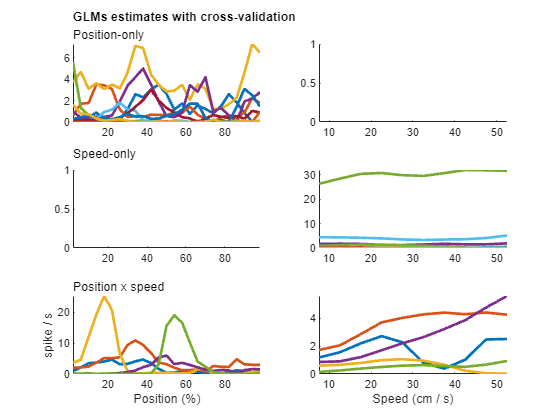

%Plotting position and speed tuning curves side by side
figure;
bincenters = glmsparams.Xbinedges(1:end-1) + glmsparams.Xbinsize / 2;
mX = max(GLMs_cv.mapX, [], 'all');
mS = max(GLMs_cv.mapS, [], 'all');

modelList = [1 2 3];
modelNames = {'Position-only', 'Speed-only', 'Position x speed'};
nmodels = numel(modelList);

for imodel = 1:nmodels
    if sum(GLMs_cv.bestmodel == modelList(imodel)) > 0
        subplot(nmodels,2,(imodel-1)*2 + 1);
        plot(GLMs_cv.Xbincenters, GLMs_cv.mapX(GLMs_cv.bestmodel == modelList(imodel),:)','linewidth', 2);
        subtitle(modelNames{imodel});
        mX = max(GLMs_cv.mapX(GLMs_cv.bestmodel == modelList(imodel),:), [], 'all');
        if ~isnan(mX)
            set(gca,'Ylim', [0 mX]);
        end
        set(gca,'Xlim', [GLMs_cv.Xbincenters(1) GLMs_cv.Xbincenters(end)],'Box', 'off','TitleHorizontalAlignment','left');
        
        subplot(nmodels,2,(imodel-1)*2 + 2);
        plot(GLMs_cv.Spdbincenters, GLMs_cv.mapS(GLMs_cv.bestmodel == modelList(imodel),:)','linewidth', 2);
        mS = max(GLMs_cv.mapS(GLMs_cv.bestmodel == modelList(imodel),:), [], 'all');
        if ~isnan(mS)
            set(gca,'Ylim', [0 mS]);
        end
        set(gca,'Xlim', [GLMs_cv.Spdbincenters(1) GLMs_cv.Spdbincenters(end)],'Box', 'off','TitleHorizontalAlignment','left');
    end
end
%labels title etc
subplot(nmodels,2, 2*nmodels - 1);
xlabel('Position (%)');
ylabel('spike / s');

subplot(nmodels,2, 2*nmodels);
xlabel('Speed (cm / s)');

subplot(nmodels,2, 1);
title('GLMs estimates with cross-validation')

Contrast the tuning curves derived from the GLM with those originating from the traditional place field analysis for cells #1, #18, and #27. What insights can be drawn from this comparison?

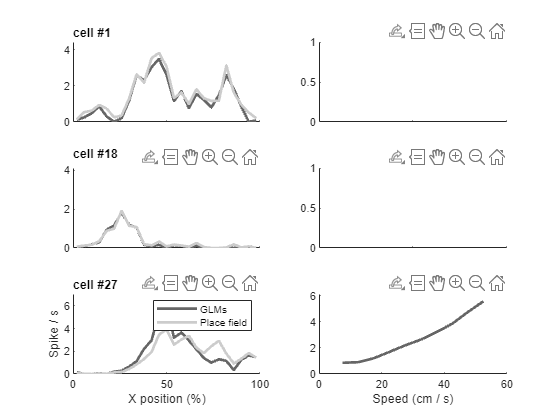

%Running the place field analysis.
mapsparams = DefineMapsParams(Nav,Spk);
Maps = MapsAnalyses2D(Nav, Spk.spikeTrain, mapsparams);

%IDs of cells to plot
cellList = [1 18 27]; 

figure;
for icell = 1:numel(cellList)
    %plotting the spatial profiles for both methods
    subplot(numel(cellList), 2, (icell-1)*2 + 1);
    plot(GLMs_cv.Xbincenters, squeeze(GLMs_cv.mapX(cellList(icell),:)), 'Color', [0.4 0.4 0.4], 'linewidth', 2);
    hold on;plot(GLMs_cv.Xbincenters, squeeze(Maps.mapXY(cellList(icell),:,2)), 'Color', [0.8 0.8 0.8], 'linewidth', 2);
    
    %finding the maximium response for scaling purposes
    mX1 = max(GLMs_cv.mapX(cellList(icell),:), [], 'all');
    mX2 = max(Maps.mapXY(cellList(icell),:,1), [], 'all');
    mX = max(mX1, mX2);
    if ~isnan(mX)
        set(gca, 'Ylim', [0 1.1*mX]);
    end
    
    %Legend etc
    title(['cell #' num2str(cellList(icell))])
    set(gca,'box', 'off','TitleHorizontalAlignment','left')
    if icell ~= numel(cellList)
        set(gca, 'XtickLabel', []);
    else
        xlabel('X position (%)')
        ylabel('Spike / s')
        legend({'GLMs', 'Place field'})
    end

    %Plotting the speed profile for the same cell
    subplot(numel(cellList), 2, (icell-1)*2 + 2);
    plot(GLMs_cv.Spdbincenters, squeeze(GLMs_cv.mapS(cellList(icell),:)), 'Color', [0.4 0.4 0.4], 'linewidth', 2);
    
    %Scaling
    mS = max(GLMs_cv.mapS(cellList(icell),:), [], 'all');
    if ~isnan(mS)
        set(gca, 'Ylim', [0 1.1*mS]);
    end

    %Legend etc
    set(gca,'box', 'off');
    if icell ~= numel(cellList)
        set(gca, 'XtickLabel', []);
    else
        xlabel('Speed (cm / s)');
    end
end